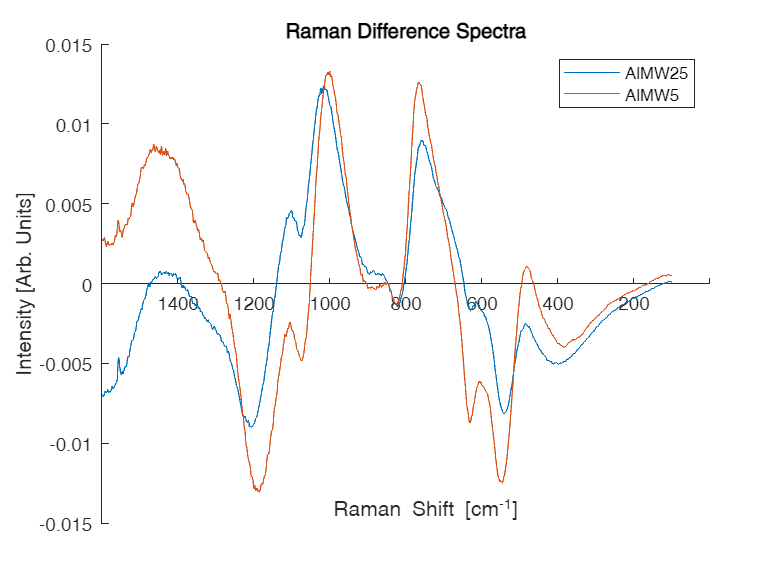

%A script that opens all csvs in a a specified directory and subtracts them
%from a centroid raman spectra

%clearing crap
clear all
clf

%selecting fodler to loop through
folder = "C:\Users\Jack\MATLAB Drive\PhD Work\Raman Plotter_050524\Plot Data\Padova";
centroid = "C:\Users\Jack\MATLAB Drive\PhD Work\Raman Plotter_050524\Plot Data\Padova\JC_Padova_MW0_5th_bas_cut_ther_vect_130624.csv";
centroid = readtable(centroid); %importing centroid

%extracting full list of files
files = dir(fullfile(folder, "*.csv"));

    %storege counter
    j=1;

%looping through and importing all folders
for i = 1:length(files)

    %full file path
    path = fullfile(folder, files(i).name);

    %importing data
    import = readtable(path);

    %subtracting from centroid
    import{:,2} = import{:,2} - centroid{:,2};

    %checking that sum of import difference column is not zero
    if not(sum(import{:,2})==0)

        %storing data if it is the first
        if j == 1

            data = import;
        
        else

            %concatenating columns
            data = [data import(:,2)];

        end

    end
    
    %growing storage counter
    j = j + 1;

end

%looping through data 
for k = 2:width(data)

    %plottting data
    plot(data{:,1},data{:,k})

    hold on %plotting on same graph

end

%labelling gprah
%xlabel("Raman Shift [cm^{-1}]")
xlabel("Raman Shift [cm^{-1}]","Position", [500, -0.015]) %moves X axis label if needed
ylabel("Intensity [Arb. Units]")
title("Raman Difference Spectra")
legend(data.Properties.VariableNames{2:end}); % Omitting the first column header

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
% ax.YAxisLocation = "origin";
set(gca, 'xdir','reverse');
box off;

hold off %ending plotting